# steering angle 값의 변화 (d = 2, 5, 10, 15, 20, 30)에 따른 off-tracking distance D를 구하라

clear all; close all;

L = 2.7; % L = wheelbase (m)
track = 1.572; % track (m)

%% off-tracking distance
steering_angle = [2, 5, 10, 15, 20, 30]; % deg
steering_angle_rad = deg2rad(steering_angle);

Delta = [2, 5, 10, 15, 20, 30]

Delta =      2     5    10    15    20    30


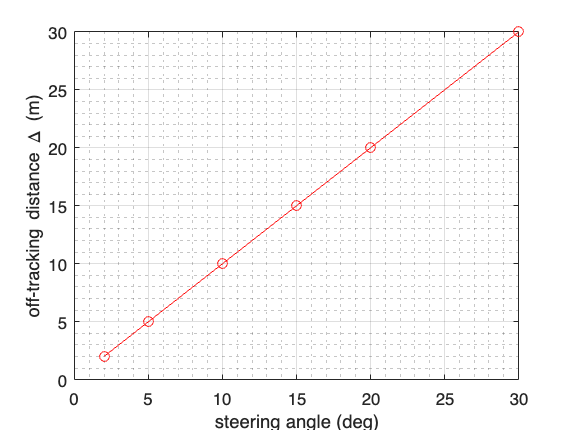


R = L ./ steering_angle_rad; % Truning Radius (m) Delta = L^2./(2*R); % Delta = D = off-track (m)
figure(1); clf;
plot(steering_angle, Delta,'-ro');
xlabel('steering angle (deg)');
ylabel('off-tracking distance \Delta (m)');
grid on; grid minor; box on;

# 이 차량의 steering angle이 sine 파형 (주기 = 20 sec, 진폭 d = 5o, 20o) 으로 변화할 때 앞바퀴와 뒷바퀴의 궤적을 그려라.

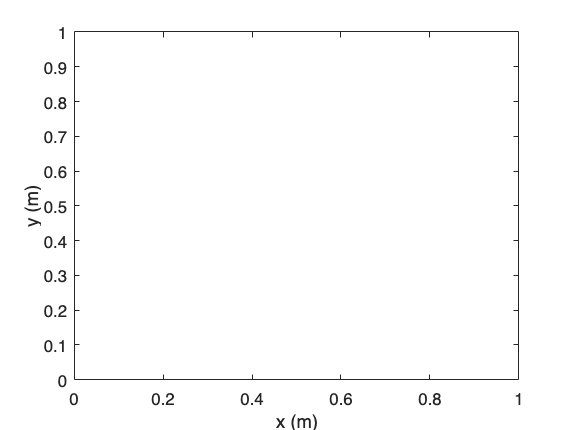

L = 2.7; % L = wheelbase (m) for a bicycle model %% steering angle = sine wave, 0.05 Hz, Amplitude = 5, 25
dt = 0.01;
t = 0:dt:20-dt;
T = 20;
f = 1/T;
sta_amp = 30;
sta = sta_amp * cosd(linspace(0,360,length(t))); % steering angle step vector (deg)

%% initial state
figure(1); clf; hold on; box on;
xlabel('x (m)'); ylabel('y (m)');


% time step size (sec)
% time step vector (sec)
% sine wave period (T = 20 sec)
% frequency = 1/T
% Steering Angle Amplitude = 30 (deg)
v_x= 0;
v_y= 0;
theta = 0;
cmd_sta = deg2rad(0); % initial command of steering angle (0 rad)
% vehicle initial speed to x-dir (0 m/sec)
% vehicle initial speed to y-dir (0 m/sec)
% vehicle inital yaw angle (0 rad)
v = 1; % vehicle speed to forward-dir = 1 m/s (v = sqrt(v_x^2 + v_y^2))


fd = [0, 0]; % Coord of initial front wheel center = (0, 0)
fdx = cos(theta)*fd(1) - sin(theta)*fd(2);
fdy = sin(theta)*fd(1) + cos(theta)*fd(2);
rd = [-L, 0]; % Coord of initial rear wheel center = (0, 0)
rdx = cos(theta)*rd(1) - sin(theta)*rd(2);
rdy = sin(theta)*rd(1) + cos(theta)*rd(2);
[updatedFx, updatedFy, updatedRx, updatedRy, updatedVx, updatedVy] = ... veh_obj(theta, cmd_sta, fdx, fdy, rdx, rdy, v_x, v_y);
vehicle = fill(updatedVx,updatedVy,'w','EraseMode','normal');
Ffw = fill(updatedFy,updatedFy,'r','EraseMode','normal'); % front wheel fill object Frw = fill(updatedRx,updatedRy,'b','EraseMode','normal'); % rear wheel fill object pd = plot([fdx rdx],[fdy rdy],'k','LineWidth',2); % driveshaft line object
track_fx = zeros(1,2); % front wheel center (x,y) position
track_rx = zeros(1,2); % rear wheel center (x,y) position
% front wheel track line object
Ltrack_fw = plot(track_fx(:,1),track_fx(:,2),'r','LineWidth',2);
% rear wheel track line object
Ltrack_rw = plot(track_rx(:,1),track_rx(:,2),'b:','LineWidth',2); plot(0,0,'rx'); % plot front wheel initial (x,y) position (Origin of the coord)



for i = 1:1:length(t)
    cmd_sta = deg2rad(sta(i)) - theta;
    v_x = v_x + v * cos( theta + cmd_sta ) * dt;
    v_y = v_y + v * sin( theta + cmd_sta ) * dt;
    theta = theta + v * tan(cmd_sta)/L * dt;
    fdx = cos(theta)*fd(1) - sin(theta)*fd(2);
    fdy = sin(theta)*fd(1) + cos(theta)*fd(2);
    rdx = cos(theta)*rd(1) - sin(theta)*rd(2);
    rdy = sin(theta)*rd(1) + cos(theta)*rd(2);
[updatedFx, updatedFy, updatedRx, updatedRy, updatedVx, updatedVy] ... = veh_obj(theta, cmd_sta, fdx, fdy, rdx, rdy, v_x, v_y);
set(vehicle, 'Xdata', updatedVx, 'Ydata', updatedVy); set(Ffw, 'Xdata', updatedFx,'Ydata', updatedFy); set(Frw, 'Xdata', updatedRx,'Ydata', updatedRy);
    log_fw(i,:) = [fdx+v_x fdy+v_y];
    log_rw(i,:) = [rdx+v_x rdy+v_y];
set(pd, 'Xdata', [dfx+v_x drx+v_x],'Ydata',[dfy+v_y dry+v_y]); % Update driveshaft set(Ltrack_fw, 'Xdata', log_fw(:,1),'Ydata',log_fw(:,2)); % Update track of fw set(Ltrack_rw, 'Xdata', log_rw(:,1),'Ydata',log_rw(:,2)); % Update track of rw
title(strcat('steering angle : ',num2str(rad2deg(cmd_sta)),'(deg)' )); axis equal; grid on;
axis([v_x-11 v_x+9 -3.5 3.5])
drawnow limitrate
    F(i) = getframe(gcf);
end

% Redraw whole simulation
axis([-5 25 -3.5 3.5])
title('result')
drawnow limitrate
F(i+1) = getframe(gcf);
%% save as vedio
v = VideoWriter('sim_off_track_sine.avi');
v.FrameRate = 100;
open(v);
for t = 1 : length(F)
    writeVideo(v,F(t));
end
for t2 = 1:1:100
writeVideo(v,F(length(F))); % 마지막 frame 유지
end
close(v);